# Edge Detection

### CONVOLUTION

A = [zeros(5, 10); ones(5, 10)]

A =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1


B = [1, 0; 0, -1]

B =      1     0
     0    -1



conv2(A, B)

ans =      0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     0
     1     0     0     0     0     0     0     0     0     0    -1
     1     0     0     0     0     0     0     0     0     0    -1
     1     0     0     0     0     0     0     0     0     0    -1
     1     0     0     0     0     0     0     0     0     0    -1


### EDGE DETECTION

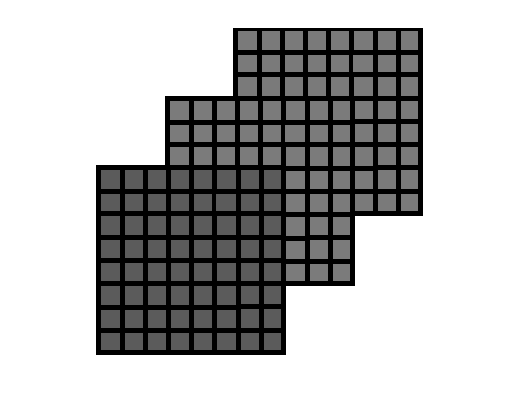

I = imread("colors.png");
I = rgb2gray(I);
imshow(I);

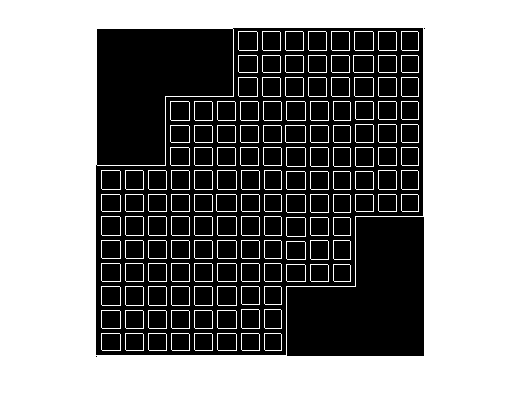

e = conv2(I, B) .* conv2(B, I);
imshow(e)

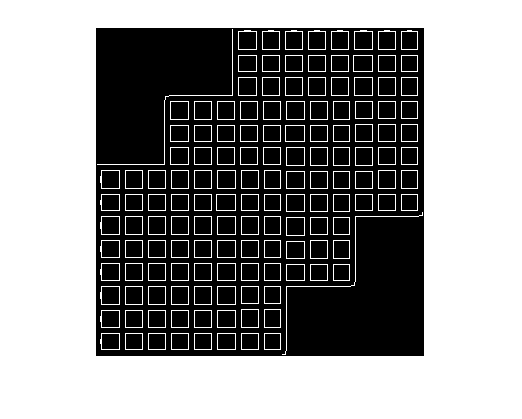


e2 = edge(I, 'Canny');


imshow(e2);